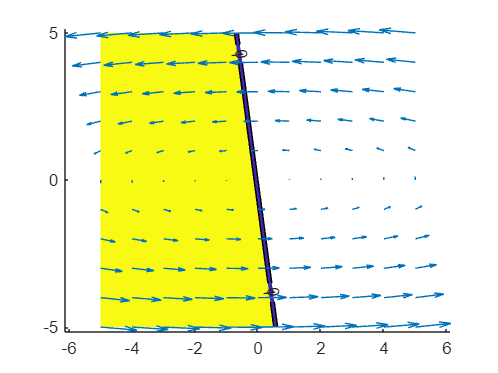

clear all
close all
A1 = [-1 -100;
    10 -1];
A2 = [1 10;
    -100 1];
E12 = [-8 -1];
E21 = [2 -1];
Q = [E12; E21].'*[0 1; 1 0] * [E12; E21];
R12 = eye(2); R21 = eye(2);

dx1 = @(x) A1.*x; %function desribing q1
dx2 = @(x) A2.*x; %function desribing q2

%plotting settings
min = -5;
max = 5;
stepsize = 1;
figure()
%plotting everything individually to validate functionality
[X,Y,u,v] = vectorfield(A1,min,max,stepsize);
hold on

[X,Y,p] = valuefield(E12,min,max,stepsize);
contourf(X,Y,p,[0 1],'ShowText','on')

quiver(X,Y,u,v)
hold off

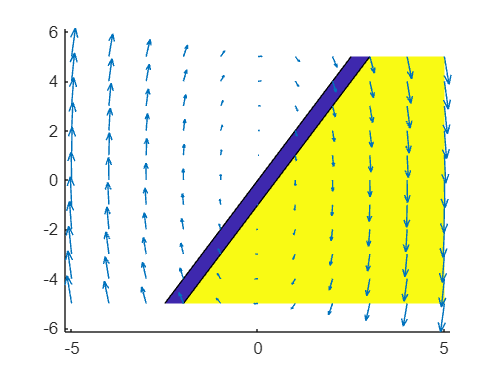


figure()
hold on
[X,Y,p] = valuefield(E21,min,max,stepsize);
contourf(X,Y,p,[0 1])

[X,Y,u,v] = vectorfield(A2,min,max,stepsize);
quiver(X,Y,u,v)



hold off

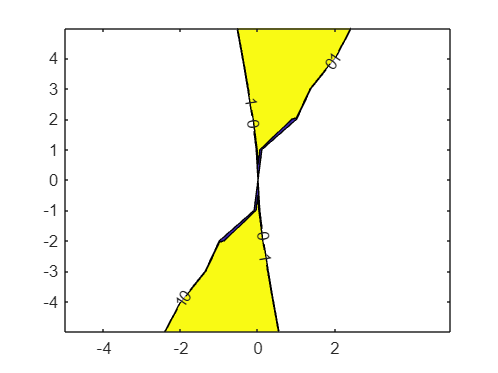


[X,Y,Qp] = Qfield(Q,min,max,stepsize);
contourf(X,Y,Qp,[0 1],'ShowText','on')

figure()
clf;
hold on

min = -1

min = -1

max = 5

max = 5

stepsize = 0.01;
[X,Y,Qp] = Qfield(Q,min,max,stepsize);

contourf(X,Y,Qp,[0 0.1])

stepsize = 0.1

stepsize = 0.1000

[X,Y,u,v] = vectorfield(A1,min,max,stepsize);
[X,Y,Qp] = Qfield(Q,min,max,stepsize);
map = zeros(length(u))

map =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0 

map(Qp>=0) = 1

map =      0     0     0     0     0     1     1     1     1     1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     1     1     1     1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     1     1     1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     1     1     1     1     0     0     0     0 

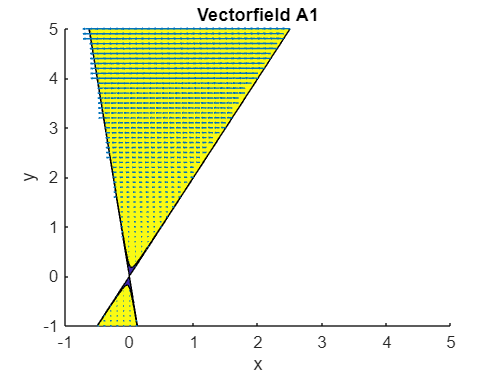

quiver(X,Y,u.*map,v.*map)
title('Vectorfield A1')
xlabel('x'); ylabel('y')
hold off


mean(mean(v.*map))

ans = 0.6274


figure()
clf;
hold on

stepsize = 0.1;
[X,Y,Qp] = Qfield(Q,min,max,stepsize);

contourf(X,Y,Qp,[0 0.1])

stepsize = 0.1

stepsize = 0.1000

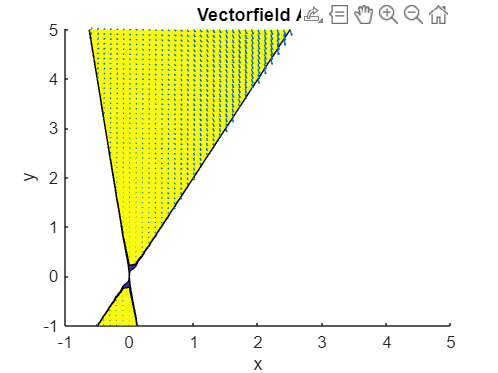

[X,Y,u,v] = vectorfield(A2,min,max,stepsize);
[X,Y,Qp] = Qfield(Q,min,max,stepsize);
map = zeros(length(u));
map(Qp>=0) = 1;


quiver(X,Y,u.*map,v.*map)
title('Vectorfield A2')
xlabel('x'); ylabel('y')
hold off

x =     -5    -4    -3    -2    -1     0     1     2     3     4     5


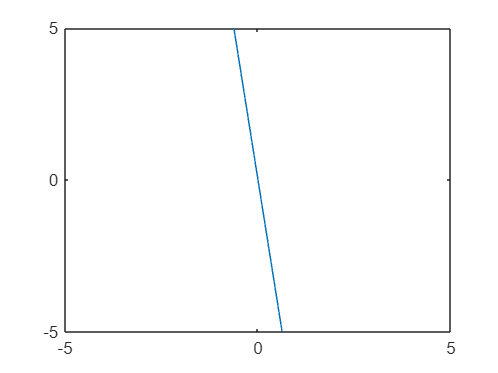

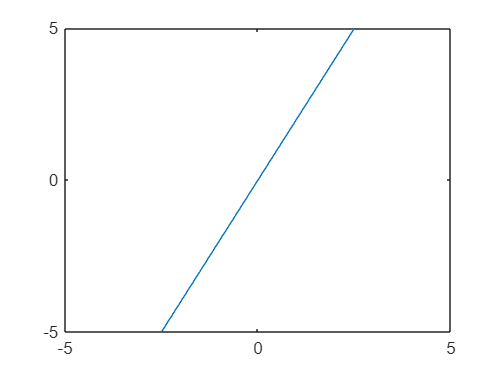

figure()

x = min:stepsize:max
plot(x,-8*x)
ylim([-5,5]); xlim([-5,5])

plot(x,2*x)
ylim([-5,5]); xlim([-5,5])


eig(A1)

ans =   -1.0000 +31.6228i
  -1.0000 -31.6228i


eig(A2)

ans =    1.0000 +31.6228i
   1.0000 -31.6228i
